**Project - Equations of motion matlab script**

**Initialize**

% syms mc mp x dx l th dth g F Fcart Fpend ddx ddth s Fdist bc bp
mc=0.9+0.1; 
mp=0.08887;
l = 0.175;
l= 0.36022/2;
g = 9.82;
b = 8.5;

**Without Disturbance linear**

% E = [(mc+mp)*ddx == (mp*l*ddth)/2 + F - bc*dx, (mp*l^2*ddth)/4 == (mp*ddx*l)/2 + (mp*g*l*th)/2 - bth*dth];
% E = [(mc+mp)*ddx - mp*l*ddth == F - bc*dx, mp*l^2*ddth + mp*ddx*l - mp*g*l*th == -Fdist - bth*dth];
% S = solve(E,ddx,ddth);
% S.ddx
% S.ddth



**With Disturbance linaer**

% E1 = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fdist-Fpend];
% S1 = solve(E1,ddx,ddth);
% S1.ddx;
% S1.ddth;

**Nonlinear**

% E2 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-Fcart, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -Fpend];
% S2 = solve(E2, ddx, ddth);
% S2.ddx;
% S2.ddth;

**Fpend and Fcart are b * x/th**

% E3 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-b*dx, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -b*dth];
% S3 = solve(E3, ddx, ddth);
% S3.ddx;
% S3.ddth;

**State Space Model**

C = [0 1 0 0;
     1 0 0 0];
s = tf('s'); 
S = [s 0 0 0;
     0 s 0 0;
     0 0 s 0;
     0 0 0 s];
  
A = [0 0 1 0;
     0 0 0 1;
     0 (-g*mp)/(mc+2*mp) 0 0 ;
     0 -(g*(mp+mc))/(l*(mc+2*mp)) 0 0]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   -0.7410         0         0
         0  -50.4081         0         0


  
B = [0 0;
     0 0;
     1/(mc+2*mp) b/(l*(mc+2*mp));
     -1/(l*(mc+2*mp)) -(mc+mp)/(l^2*mp*(mc+2*mp))]

B =          0         0
         0         0
    0.8491   40.0711
   -4.7143 -320.6976



% u = [F-Fcart; -Fpend];
 
system = ss(A,B,C,0)

system =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -0.741       0       0
   x4       0  -50.41       0       0
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3  0.8491   40.07
   x4  -4.714  -320.7
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Observability and Controlability**

observability = obsv(system)

observability =          0    1.0000         0         0
    1.0000         0         0         0
         0         0         0    1.0000
         0         0    1.0000         0
         0  -50.4081         0         0
         0   -0.7410         0         0
         0         0         0  -50.4081
         0         0         0   -0.7410


rank(observability); % Full rank

controlability = ctrb(system)

controlability = 	1.0e+04 *

         0         0    0.0001    0.0040         0         0    0.0003    0.0238
         0         0   -0.0005   -0.0321         0         0    0.0238    1.6166
    0.0001    0.0040         0         0    0.0003    0.0238         0         0
   -0.0005   -0.0321         0         0    0.0238    1.6166         0         0


rank(controlability); % Full rank

## **Pole Placement Method**

**Extended Matrices**

A_e = [A zeros([4 2]);
       C zeros([2 2])]

A_e =          0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0   -0.7410         0         0         0         0
         0  -50.4081         0         0         0         0
         0    1.0000         0         0         0         0
    1.0000         0         0         0         0         0


B_e = [B;
       zeros([2 2])];
C_e = [C zeros([2 2])];

**Pole Placement - settling of +/-3% in 1 second.**

ts = 1;
alpha = 3;
sigma = -log10((alpha/100)/100)/ts

sigma = 3.5229


poles = -[sigma+1i sigma-1i sigma*5+1i sigma*5-1i sigma*6+1i sigma*6-1i]

poles =   -3.5229 - 1.0000i  -3.5229 + 1.0000i -17.6144 - 1.0000i -17.6144 + 1.0000i -21.1373 - 1.0000i -21.1373 + 1.0000i


% Tried to plot with poles on the real axis. This did not work either.
% poles = -[sigma sigma*5 sigma*7 sigma*12 sigma*18 sigma*22]

Fe = -place(A_e, B_e, poles);
F = Fe(1:2, 1:4)

F = 	1.0e+03 *

   -2.7754   -3.2301   -0.1843   -0.0992
    0.0406    0.0482    0.0027    0.0016


Fi = Fe(1:2, 5:6)

Fi = 	1.0e+04 *

   -2.9333   -1.2906
    0.0429    0.0188



% feedback = A_e + B_e * Fe;
% eigMat = eig(A_e + B_e * Fe);

## 3. Observer design

Pole selection

OBS = [-sigma*5.1+1i -sigma*5.1-1i -sigma*6.1+1i -sigma*6.1-1i]

OBS =  -17.9667 + 1.0000i -17.9667 - 1.0000i -21.4896 + 1.0000i -21.4896 - 1.0000i


%OBS = [OBS1-0.1 OBS1-0.2 OBS1-0.3 OBS1-0.4];

Observer design    

L = -place(system.A', system.C', OBS).'

L =     1.5006  -39.3639
  -39.5486   -2.6718
   30.3079 -383.3098
 -336.4734  -52.7727


Anti windup

MP = [-sigma*5.5+1i -sigma*5.5-1i -sigma*6.5+1i -sigma*6.5-1i]

MP =  -19.3758 + 1.0000i -19.3758 - 1.0000i -22.8987 + 1.0000i -22.8987 - 1.0000i


%MP = [-15 -20 -25 -30]
M = -place((A + L * C)', F', MP).'

M =     0.0064    0.3976
   -0.0213   -1.4178
    0.1592   10.1013
   -0.4205  -28.0809


## **Transfer functions and PID controller **

## **Not used yet.**

SA = inv(S-A)

SA =
 
  From input 1 to output...
       1
   1:  -
       s
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
                         -0.741 s - 1.431e-14
   1:  ---------------------------------------------------------
       s^4 + 3.442e-15 s^3 + 50.41 s^2 - 8.372e-14 s - 3.738e-16
 
             s - 3.65e-15
   2:  -------------------------
       s^2 - 4.154e-15 s + 50.41
 
                 -0.741 s - 9.917e-14
   3:  ----------------------------------------
       s^3 + 5.84e-16 s^2 + 50.41 s + 1.326e-13
 
                -50.41
   4:  -------------------------
       s^2 - 4.154e-15 s + 50.41
 
  From input 3 to output...
                     1
   1:  -----------------------------
       s^2 + 2.629e-15 s - 6.708e-17
 
   2:  0
 
       1
   3:  -
       s
 
   4:  0
 
  From input 4 to output...
                                -0.741
   1:  ---------------------------------------------------------
       s^4 + 1.187e-14 s^3 + 50.41 s^2 + 5.005e-13 s - 8.506e-14
 

% G8 = C*SA*B

[Gnum,Gden] = ss2tf(A,B,C,[0 0; 0 0], 1)

Gnum =          0         0   -4.7143         0   -0.0000
         0         0    0.8491   -0.0000   46.2939


Gden =     1.0000         0   50.4081         0         0


SS2TF1 = Gnum(1,:);
SS2TF2 = Gnum(2,:);
 
G1 =tf(SS2TF1, Gden)

G1 =
 
  -4.714 s^2 - 3.14e-15
  ---------------------
     s^4 + 50.41 s^2
 
Continuous-time transfer function.



G2 =tf(SS2TF2, Gden)

G2 =
 
  0.8491 s^2 - 5.058e-15 s + 46.29
  --------------------------------
          s^4 + 50.41 s^2
 
Continuous-time transfer function.



**PID**

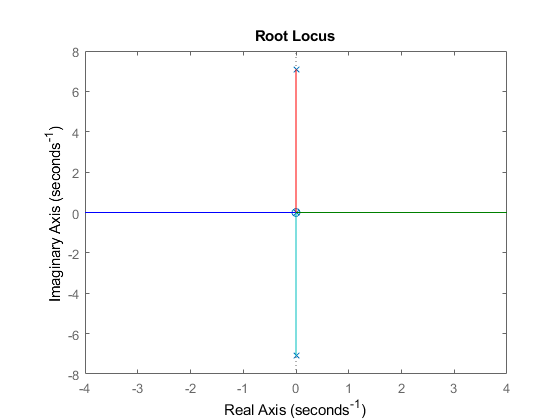

Kp = 50;
Ti = 0.1;
Td = 0.1;

Ks = Kp * (1 + 1 / (Ti * s) + Td * s);
rlocus(G1);

% step(Ks*G2);

% pid(Kp,Ti,Td)


% rlocus(G1);
% rlocus(G2);
% It uses rational numbers instead of decimals.
%  G = C*inv((s-A))*B*u
%  simplify(G);